# Write Down Virtual Power Dynamic Equations out from defined wrenches and solid twists acting on the system

## Related Slides:

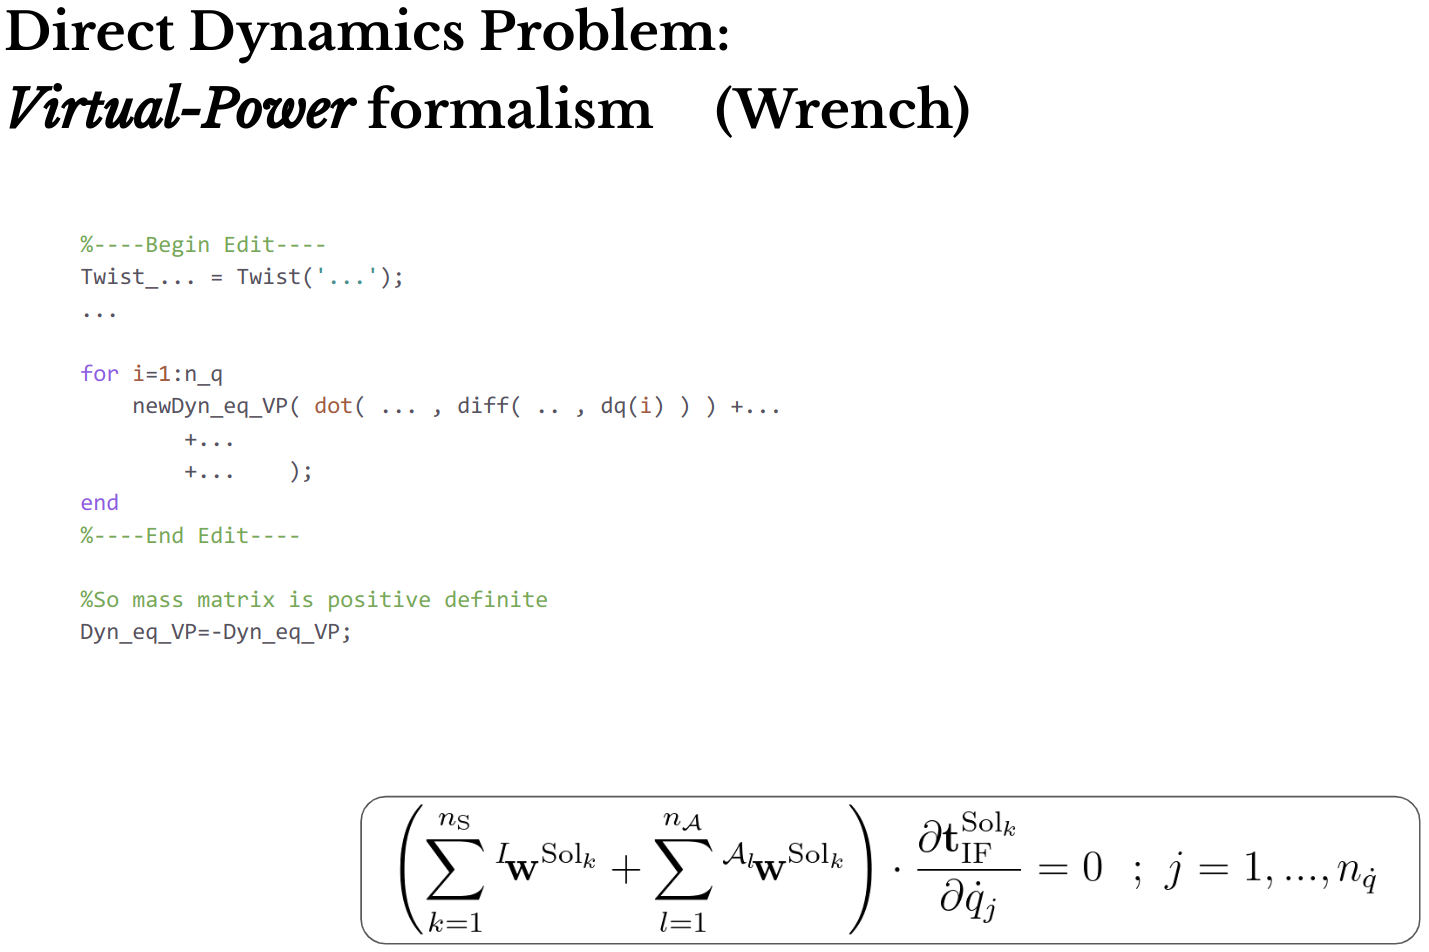

clearDyn_eq_NE
clearDyn_eq_VP

n_Solids=length(Solids);

Initialize the `genforzes` vector, it will contain the sum of all the generalized forces acting over the system (non external Solids), this vector will just contain the Systematized Virtual Power Dynamic Equations.

genforces=sym(zeros(length(dq),1));
V=[];
M_V_dV=[];
solid_base_number=zeros(1,n_Solids);
solid_point_number=zeros(1,n_Solids);

From the first Solid to the last (excluding External Solids)

for k=1:n_Solids
    if not(Solids(k).isExt)

Determine sum of wrenches over the Solid at this iteration as:

        sum_wrenches=Vector6D(Vector3D([0,0,0]',[]),Vector3D([0,0,0]',[]),[]);

Sum of all the inertia action wrenches over the Solid

        for j=1:length(Solids(k).IActions)
            solid_base_number(k)=Solids(k).inertia_tensor.Base;
            solid_point_number(k)=Solids(k).inertia_tensor_point;
            sum_wrenches=sum_wrenches+Solids(k).IActions(j).inBase(solid_base_number(k)).inPoint(solid_point_number(k));  
        end

Sum of all the constraint action wrenches over the Solid

        for j=1:length(Solids(k).CActions)
            sum_wrenches=sum_wrenches+Solids(k).CActions(j).inBase(solid_base_number(k)).inPoint(solid_point_number(k));  
        end

Sum of all the constraint reaction wrenches over the Solid (note the minus sign)      

        for j=1:length(Solids(k).CReactions)
            sum_wrenches=sum_wrenches-Solids(k).CReactions(j).inBase(solid_base_number(k)).inPoint(solid_point_number(k));  
        end

Sum of all the "Other" (remaining) action wrenches over the Solid

        for j=1:length(Solids(k).Actions)
            sum_wrenches=sum_wrenches+Solids(k).Actions(j).inBase(solid_base_number(k)).inPoint(solid_point_number(k));  
        end

Sum of all the "Other" (remaining) remaining reaction wrenches over the Solid (note the minus sign)

        for j=1:length(Solids(k).Reactions)
            sum_wrenches=sum_wrenches-Solids(k).Reactions(j).inBase(solid_base_number(k)).inPoint(solid_point_number(k));  
        end

        newDyn_eq_NE(-sum_wrenches);

Determine the Twist of the Solid

        Twist_Solid=Twist(InertialFrame_name,NamesSolids(k).Solid_name);
        Twist_Solid=Twist_Solid.inBase(solid_base_number(k));
        if (Solids(k).first_mass_moment.Base == solid_base_number(k)) && (Solids(k).inertia_tensor.Base == solid_base_number(k))
        V=[V;[Twist_Solid.MV;Twist_Solid.FW]];
        M_V_dV= blkdiag(M_V_dV,...
            [Solids(k).mass * eye(3),         -vecttoskew(Solids(k).first_mass_moment.Value);
            -vecttoskew(Solids(k).first_mass_moment.Value)',  Solids(k).inertia_tensor.Value]...
            );
        else
           error(['Solid ',Solid_name,' its first inertia moment and intertia tensor bases are not coincident. Code must be improved to handle this case']);
        end

For each generalized velocity determine the virtual power of all the actions over the solid, as the product of the sum of wrenches of each solid times the Jacobian of the twist with respect to the generalized velocity.

This is the resultant generalized force acting on the system for the motion generated by this generalized velocity alone (having a value of 1).

        for i=1:length(dq)
            genforces(i,1)=genforces(i,1)+dot(sum_wrenches,diff(Twist_Solid,dq(i)));
        end

    end
end

The sign is changed when adding the generalized forces to the Virtual Power dynamic equations vector ( `Dyn_eq_VP `) so the associated mass matrix is definite or semidefinite positive

newDyn_eq_VP(-genforces);